# **Analysis of the Burgers equation by vanilla DMD**

First run TanSacNet/code/setpath

Requirements: MATLAB R2022b 

Contact address: Shogo MURAMATSU, Faculty of Engineering, Niigata University, 8050 2-no-cho Ikarashi, Nishi-ku, Niigata, 950-2181, JAPAN http://msiplab.eng.niigata-u.ac.jp  

Copyright (c) 2023, Hayato Obara and Shogo MURAMATSU, All rights reserved.

clc, clear
close all

% Data folder
datafolder = "../../../data/";


Parameters

nu = 0.05;
% td-DMD
nDelay = 1;

## Input data

filenameinput = "burgerseq";
if exist(datafolder+filenameinput+"nu_"+replace(num2str(nu),'.','_')+".mat","file")~=2
    main_burgerseq_gen(datafolder+filenameinput,nu)
else
    disp("Data found!")
end

Data found!


Sload = load(datafolder+filenameinput+"nu_"+replace(num2str(nu),'.','_'),"T","X","DataT","dt","dx");
T = Sload.T;
X = Sload.X;
dt = Sload.dt;
dx = Sload.dx;
DataT = Sload.DataT;

## **Data visualisation**

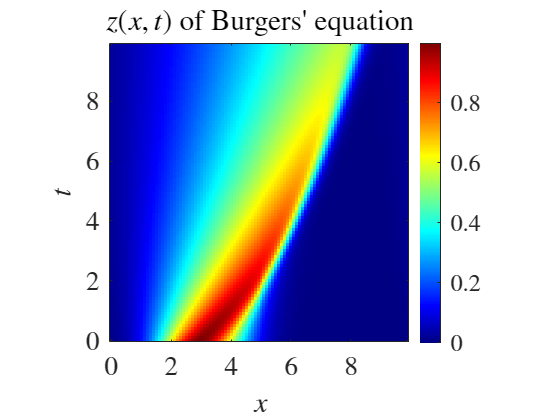

figure
disp_imagesc_(T,X,DataT," $z(x,t)$ of Burgers' equation");

nT = size(DataT,1);
nX = size(DataT,2);


### vanilla td-DMD

% Construction of Hankel matrix
x = DataT;

ts = [];
H = [];
%nRange = size(x,1)-1;
nRange = size(x,1);
for k = 0:nRange-nDelay-1
    xkT = [];
    for iDelay = 0:nDelay
        xkT = cat(2,xkT,x(k+iDelay+1,:));
    end
    H = cat(2,H,xkT.');
end
H

H =     0.0111    0.0092    0.0094    0.0098    0.0102    0.0107    0.0112    0.0116    0.0121    0.0125    0.0130    0.0134    0.0138    0.0142    0.0146    0.0150    0.0154    0.0158    0.0161    0.0165    0.0168    0.0171    0.0175    0.0178    0.0181    0.0184    0.0187    0.0189    0.0192    0.0195    0.0197    0.0200    0.0202    0.0204    0.0207    0.0209    0.0211    0.0213    0.0215    0.0217    0.0219    0.0221    0.0222    0.0224    0.0226    0.0227    0.0229    0.0230    0.0232    0.0233
    0.0150    0.0150    0.0149    0.0151    0.0154    0.0158    0.0162    0.0166    0.0170    0.0175    0.0179    0.0183    0.0187    0.0191    0.0195    0.0199    0.0203    0.0207    0.0210    0.0213    0.0217    0.0220    0.0223    0.0226    0.0229    0.0232    0.0234    0.0237    0.0240    0.0242    0.0244    0.0247    0.0249    0.0251    0.0253    0.0255    0.0257    0.0259    0.0260    0.0262    0.0264    0.0265    0.0267    0.0268    0.0270    0.0271    0.0272    0.0273    0.0275    0

Step 2 SVD of H

[U,Sgm,V] = svd(H,'econ')

U =    -0.0047    0.0034    0.0008   -0.0015    0.0005   -0.0009   -0.0006    0.0006    0.0008    0.0001   -0.0011   -0.0005    0.0018    0.0014    0.0028   -0.0027    0.0044   -0.0048    0.0069   -0.0079    0.0106   -0.0125    0.0161   -0.0192   -0.0241   -0.0288    0.0356    0.0424    0.0517    0.0614    0.0739    0.0874    0.1030    0.1205    0.1386    0.1586    0.1721    0.1814    0.1779    0.1975   -0.0762    0.0756   -0.1694    0.1217   -0.1528    0.1251   -0.1105    0.0999   -0.0803    0.0826
   -0.0057    0.0033    0.0010   -0.0014    0.0007   -0.0009   -0.0007    0.0005    0.0008    0.0002   -0.0010   -0.0001    0.0012    0.0004    0.0014   -0.0007    0.0017   -0.0010    0.0018   -0.0010    0.0017   -0.0008    0.0012   -0.0000   -0.0000    0.0016   -0.0024   -0.0048   -0.0065   -0.0102   -0.0134   -0.0191   -0.0238   -0.0322   -0.0391   -0.0518   -0.0582   -0.0685   -0.0639   -0.0896    0.0705   -0.0052    0.0991   -0.0271    0.0815   -0.1036    0.0732   -0.0473    0.0716   -0

Sgm =    44.2104         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   19.5154         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

V =    -0.0973   -0.1595    0.1750    0.1818    0.1873    0.1927   -0.1978   -0.2026    0.2065   -0.2098   -0.2118   -0.2130    0.2128    0.2119    0.2095   -0.2064    0.2021   -0.1972    0.1912   -0.1847    0.1775   -0.1699    0.1618   -0.1536   -0.1449   -0.1364    0.1277    0.1193    0.1108    0.1027    0.0947    0.0870    0.0793    0.0719    0.0644    0.0567    0.0486    0.0400    0.0327    0.0268   -0.0032    0.0127   -0.0144    0.0138   -0.0105    0.0050   -0.0047    0.0046   -0.0022    0.0019
   -0.0985   -0.1602    0.1716    0.1728    0.1709    0.1678   -0.1625   -0.1558    0.1462   -0.1350   -0.1207   -0.1048    0.0863    0.0666    0.0449   -0.0227   -0.0008    0.0241   -0.0476    0.0704   -0.0926    0.1133   -0.1327    0.1503    0.1661    0.1799   -0.1916   -0.2012   -0.2088   -0.2145   -0.2182   -0.2202   -0.2201   -0.2181   -0.2132   -0.2050   -0.1916   -0.1724   -0.1527   -0.1394    0.0264   -0.0657    0.0895   -0.0819    0.0748   -0.0459    0.0423   -0.0403    0.0258   -0

Step 3 PCT

iMode = 1

iMode = 1

ui = reshape(U(:,iMode),size(x,2),[]).'

ui =    -0.0047   -0.0057   -0.0068   -0.0080   -0.0093   -0.0109   -0.0125   -0.0144   -0.0164   -0.0186   -0.0210   -0.0235   -0.0262   -0.0291   -0.0322   -0.0354   -0.0388   -0.0423   -0.0460   -0.0497   -0.0536   -0.0575   -0.0615   -0.0655   -0.0696   -0.0737   -0.0777   -0.0817   -0.0857   -0.0896   -0.0934   -0.0970   -0.1006   -0.1040   -0.1072   -0.1102   -0.1129   -0.1155   -0.1177   -0.1197   -0.1214   -0.1227   -0.1237   -0.1243   -0.1245   -0.1243   -0.1237   -0.1227   -0.1213   -0.1195
   -0.0048   -0.0057   -0.0068   -0.0080   -0.0094   -0.0109   -0.0125   -0.0143   -0.0163   -0.0185   -0.0208   -0.0233   -0.0260   -0.0288   -0.0318   -0.0349   -0.0382   -0.0416   -0.0451   -0.0487   -0.0524   -0.0562   -0.0601   -0.0640   -0.0680   -0.0719   -0.0759   -0.0799   -0.0838   -0.0876   -0.0914   -0.0952   -0.0987   -0.1022   -0.1055   -0.1086   -0.1115   -0.1142   -0.1166   -0.1188   -0.1206   -0.1221   -0.1233   -0.1240   -0.1244   -0.1244   -0.1239   -0.1230   -0.1218   -

V0 = V(1:end-1,:);
V1 = V(2:end,:);
dtAplusI = (V1.')*pinv(V0.') 

dtAplusI =     0.9923    0.0131    0.0073   -0.0104    0.0099   -0.0110   -0.0113    0.0119    0.0123    0.0127   -0.0130    0.0134    0.0136   -0.0138    0.0139    0.0140    0.0140    0.0140    0.0139    0.0138    0.0137    0.0135    0.0133    0.0131   -0.0128    0.0125    0.0122   -0.0119    0.0116   -0.0112    0.0108   -0.0104    0.0100   -0.0096    0.0092   -0.0087    0.0084   -0.0078    0.0076   -0.0069   -0.0036    0.0050   -0.0057   -0.0096   -0.0045   -0.0042   -0.0064   -0.0056   -0.0027   -0.0043
   -0.0207    0.9813   -0.0301    0.0090   -0.0167    0.0141    0.0161   -0.0160   -0.0170   -0.0172    0.0179   -0.0181   -0.0185    0.0187   -0.0189   -0.0190   -0.0191   -0.0191   -0.0190   -0.0188   -0.0187   -0.0184   -0.0182   -0.0178    0.0175   -0.0171   -0.0167    0.0162   -0.0158    0.0153   -0.0147    0.0142   -0.0137    0.0131   -0.0125    0.0119   -0.0115    0.0106   -0.0104    0.0095    0.0049   -0.0068    0.0078    0.0131    0.0062    0.0057    0.0087    0.0076    0.00

Step 4 Discover forcinge signal

v0hat = V(1,:).';
vk = v0hat;
dtrk_ = 0;
dtr = [];
for k = 1:nRange-nDelay-1
    % True value
    vkp1 = V(k+1,:).';
    % Forcasted value
    vkp1hat = dtAplusI*vk;
    % Forcing signal
    dtrk_ = vkp1 - vkp1hat;
    % Update
    vk = vkp1;
    dtr = cat(2,dtr,dtrk_);
end

Learnable parameters

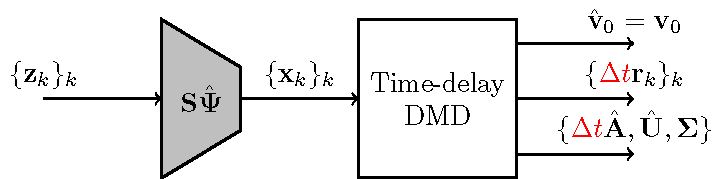

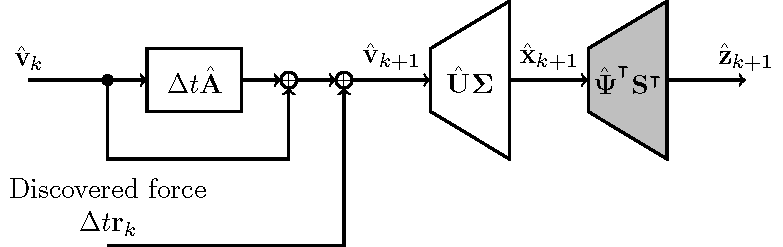

Parameters


$$\hat{\mathbf{v}}_0$$


v0hat

v0hat =    -0.0973
   -0.1595
    0.1750
    0.1818
    0.1873
    0.1927
   -0.1978
   -0.2026
    0.2065
   -0.2098



$$\{\Delta t \mathbf{r}_k\}$$


dtr

dtr = 1.0e-15 *

    0.4857    0.1943   -0.0278    0.0833   -0.1110   -0.1388   -0.0833   -0.0139    0.2498    0.0971   -0.2220   -0.2498    0.0416    0.1527   -0.1804   -0.1388    0.2082   -0.1388   -0.0416    0.2220   -0.0555    0.1249    0.2220    0.0555   -0.1249    0.3747   -0.0833    0.2637   -0.1110   -0.0833    0.0139    0.2776    0.1249    0.0555   -0.2082   -0.0416    0.3053    0.0555   -0.1249   -0.1665   -0.0833    0.0416    0.0833   -0.1943   -0.1804   -0.0833   -0.0694   -0.3747    0.2637    0.1527
   -0.0555   -0.0278    0.1665         0    0.0833   -0.3331   -0.1943    0.1665         0    0.1943   -0.1110   -0.0555   -0.1665   -0.0278    0.1110    0.0278    0.1388    0.0416    0.0555    0.1388   -0.0971   -0.0278   -0.0278    0.0416    0.1110    0.2637    0.1943   -0.0555   -0.0278   -0.1388         0   -0.2637    0.2012   -0.1214    0.1249    0.1596    0.0416    0.0399   -0.2754   -0.0898    0.0815   -0.0729   -0.0243         0   -0.1006    0.1110   -0.0555   -0.0278  


$$\mathbf{I}+\Delta t \hat{\mathbf{A}}$$


dtAplusI

dtAplusI =     0.9923    0.0131    0.0073   -0.0104    0.0099   -0.0110   -0.0113    0.0119    0.0123    0.0127   -0.0130    0.0134    0.0136   -0.0138    0.0139    0.0140    0.0140    0.0140    0.0139    0.0138    0.0137    0.0135    0.0133    0.0131   -0.0128    0.0125    0.0122   -0.0119    0.0116   -0.0112    0.0108   -0.0104    0.0100   -0.0096    0.0092   -0.0087    0.0084   -0.0078    0.0076   -0.0069   -0.0036    0.0050   -0.0057   -0.0096   -0.0045   -0.0042   -0.0064   -0.0056   -0.0027   -0.0043
   -0.0207    0.9813   -0.0301    0.0090   -0.0167    0.0141    0.0161   -0.0160   -0.0170   -0.0172    0.0179   -0.0181   -0.0185    0.0187   -0.0189   -0.0190   -0.0191   -0.0191   -0.0190   -0.0188   -0.0187   -0.0184   -0.0182   -0.0178    0.0175   -0.0171   -0.0167    0.0162   -0.0158    0.0153   -0.0147    0.0142   -0.0137    0.0131   -0.0125    0.0119   -0.0115    0.0106   -0.0104    0.0095    0.0049   -0.0068    0.0078    0.0131    0.0062    0.0057    0.0087    0.0076    0.00


$$\hat{\mathbf{U}}$$


ndim=nX;
Uhat = U(1:ndim,:);
Uhat

Uhat =    -0.0047    0.0034    0.0008   -0.0015    0.0005   -0.0009   -0.0006    0.0006    0.0008    0.0001   -0.0011   -0.0005    0.0018    0.0014    0.0028   -0.0027    0.0044   -0.0048    0.0069   -0.0079    0.0106   -0.0125    0.0161   -0.0192   -0.0241   -0.0288    0.0356    0.0424    0.0517    0.0614    0.0739    0.0874    0.1030    0.1205    0.1386    0.1586    0.1721    0.1814    0.1779    0.1975   -0.0762    0.0756   -0.1694    0.1217   -0.1528    0.1251   -0.1105    0.0999   -0.0803    0.0826
   -0.0057    0.0033    0.0010   -0.0014    0.0007   -0.0009   -0.0007    0.0005    0.0008    0.0002   -0.0010   -0.0001    0.0012    0.0004    0.0014   -0.0007    0.0017   -0.0010    0.0018   -0.0010    0.0017   -0.0008    0.0012   -0.0000   -0.0000    0.0016   -0.0024   -0.0048   -0.0065   -0.0102   -0.0134   -0.0191   -0.0238   -0.0322   -0.0391   -0.0518   -0.0582   -0.0685   -0.0639   -0.0896    0.0705   -0.0052    0.0991   -0.0271    0.0815   -0.1036    0.0732   -0.0473    0.0716  


$$\mathbf{\Sigma}$$


Sgm

Sgm =    44.2104         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   19.5154         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Step 5 w/ Discovered forcing signal

vkhat = v0hat;
%dtrk = dtr(:,1);
Xhat = (Uhat*Sgm*vkhat).';
for k = 1:nRange-nDelay-1
    dtrk = dtr(:,k);
    vkp1hat = dtAplusI*vkhat + dtrk;
    Xhat =  cat(1,Xhat,(Uhat*Sgm*vkp1hat).');
    % Update
    vkhat = vkp1hat;
end

DataHatTaprx = Xhat;

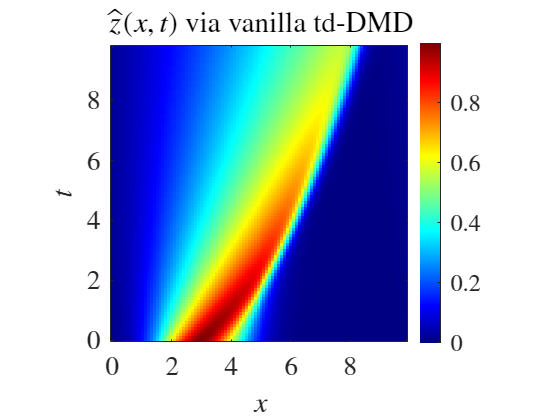

figure
ax = disp_imagesc_(T,X,DataHatTaprx," $\hat{z}(x,t)$ via vanilla td-DMD");
exportgraphics(ax,'fig03b.png')

% MSE評価
mse(DataT(1:size(DataHatTaprx,1),:),DataHatTaprx)

ans = 7.0315e-30

## Discovered forcing signal

r0 = zeros(size(v0hat),'like',v0hat);
%dtrk = dtr(:,1);
Rhat = (Uhat*Sgm*r0).';
for k = 1:nRange-nDelay-1
    dtrk = dtr(:,k);
    rkp1hat = dtrk/dt;
    Rhat =  cat(1,Rhat,(Uhat*Sgm*rkp1hat).');
    % Update
    rkhat = rkp1hat;
end

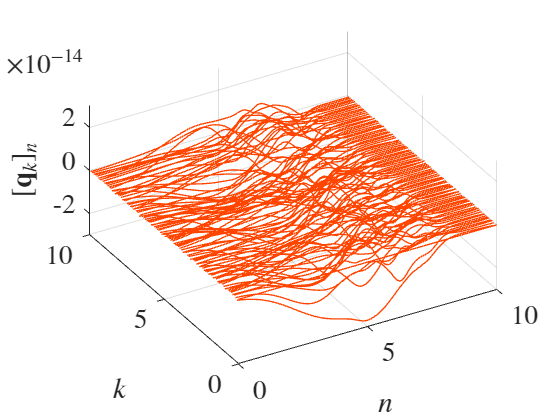

DataTdfs = Rhat;

figure
orangered = [255 69 0]/255;
ax = disp_plot3_q_(T(1:size(DataTdfs,1)),X,DataTdfs,orangered);
ax.ZLim = [-3 3]*1e-14;
exportgraphics(ax,'fig04a.png')

disp("||q_k||_2^2/(K-D)")

||q_k||_2^2/(K-D)


size(DataTdfs,1)

ans = 99

norm(DataTdfs,'Fro')/size(DataTdfs,1)

ans = 6.0610e-15

Function definition

function ax = disp_plot3_q_(T,X,DataT,c)
if nargin < 4
 c = 'blue';
end

for idx = 1:length(T)
 plot3(X,T(idx)*ones(size(X)),DataT(idx,:),...
 'Color',c,...
 'LineWidth',1)
 hold on
end
xlabel('$n$', 'Interpreter','latex')
ylabel('$k$', 'Interpreter','latex')
zlabel('$[\mathbf{q}_k]_n$', 'Interpreter','latex')
ax = gca;
ax.View = [-30 30];
ax.PlotBoxAspectRatio = [ 2 2 1];
ax.FontSize = 20;
ax.TickLabelInterpreter = 'latex';

grid on
hold off
end


function ax = disp_imagesc_(T,X,DataT,title_)
imagesc(DataT)
colormap("jet")
cb = colorbar;
cb.TickLabelInterpreter = 'latex';
title(title_,'Interpreter','latex')
xlabel('$x$','Interpreter','latex')
ylabel('$t$','Interpreter','latex')
ax = gca;
ax.PlotBoxAspectRatio = [1 1 1];
ax.XTick = 1:20:100;
ax.XTickLabel = round(X(ax.XTick));
ax.YTick = 1:20:100;
ax.YTickLabel = round(T(ax.YTick));
ax.YDir = 'normal';
ax.FontSize = 20;
ax.TickLabelInterpreter = 'latex';
end